# Find Peaks in Signals

Instructions are in the task pane to the left. Complete and submit each task one at a time.

Do not edit. This code loads and plots the data.

clear;clc
% load sampleletters.mat
m1 = readtable("user001_M_1.txt")

m1 = 28×4 table
    Time       X        Y        P  
    _____    _____    _____    _____

    34806    0.775    0.228    0.042
    34808    0.775    0.227    0.255
    34808    0.775    0.227    0.255
    34825    0.774    0.221     0.44
    34833    0.774    0.214    0.569
    34850    0.773    0.199    0.745
    34866    0.772    0.188      0.8
    34886    0.772    0.176    0.851
    34900    0.773    0.173     0.88
    34944    0.777    0.194    0.894
    34949    0.778    0.201    0.896
    34975    0.784    0.228    0.899
    34995    0.789    0.249    0.923
    35000     0.79    0.251    0.931
    35018    0.791    0.248    0.995
    35058     0.79    0.209        1


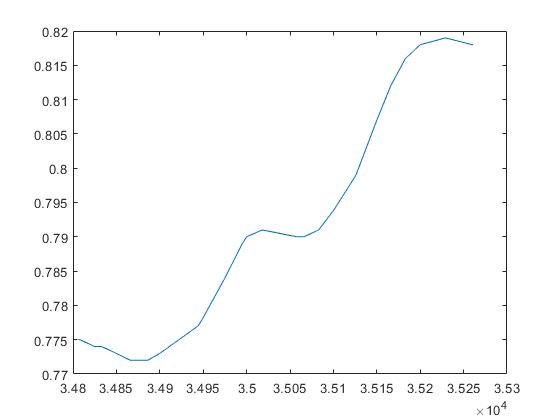

plot(m1.Time,m1.X)

Local minima and maxima are often important features of a signal. The `islocalmin` and `islocalmax` functions take a signal as input and return a logical array the same length as the signal.

`idx` `=` `islocalmin``(``x``)``;`

The value of `idx` is `true` whenever the corresponding value in the signal is a local minimum.

## Task 1

Use the `islocalmin` and `islocalmax` functions to create two logical arrays, `idxmin` and `idxmax`, respectively, that determine the local minima and maxima of `m1.X`.

idxmin = islocalmin(m1.X)

idxmin = 28×1 logical array
   0
   0
   0
   0
   0
   0
   1
   0
   0
   0


idxmax = islocalmax(m1.X)

idxmax = 28×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


Visualize the results

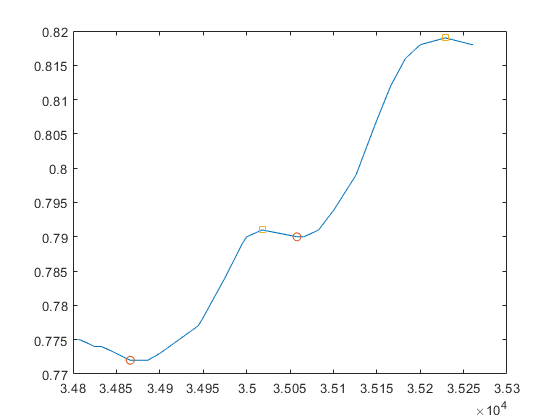

plot(m1.Time,m1.X)
hold on
plot(m1.Time(idxmin),m1.X(idxmin),"o")
plot(m1.Time(idxmax),m1.X(idxmax),"s")
hold off

Local minima and maxima are defined by computing the *prominence* of each value in the signal. The prominence is a measure of how a value compares to the other values around it. You can obtain the prominence value of each point in a signal by obtaining a second output from `islocalmin` or `islocalmax`.

`[``idx``,``p``]` `=` `islocalmin``(``x``)``;`

## Task 2

Determine the prominence values for `islocalmin(m1.X)`. Store the result in a variable called `prom`. Plot the prominence as a function of the `Time` variable of `m1`.

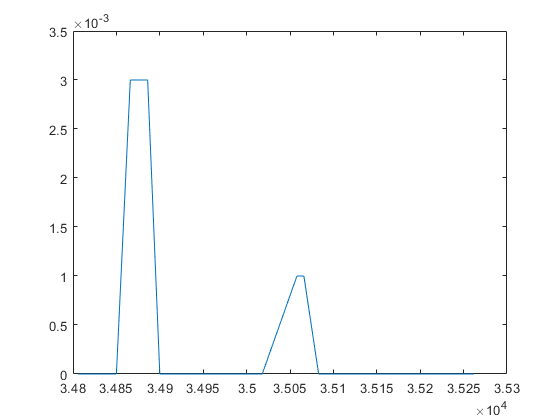

[idx,prom] = islocalmin(m1.X);
plot(m1.Time,prom)

By default, `islocalmin` and `islocalmax` find points with any prominence value above 0. This means that a maximum is defined as any point that is larger than the two values on either side of it. For noisy signals you might want to consider only minima and maxima that have a prominence value above a given threshold.

`idx` `=` `islocalmin``(``x``,``"MinProminence"``,``threshvalue``)`

When choosing a threshold value, note that prominence values can range from 0 to `range``(``x``)`.

## Task 3

Recalculate `idxmin` and `idxmax` for `m1.X` using a minimum prominence threshold of `0.1`. Copy the plotting code from task 1 to visualize the result.

idxmin = islocalmin(m1.X,"MinProminence",0.1)

idxmin = 28×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


idxmax = islocalmax(m1.X,"MinProminence",0.1)

idxmax = 28×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


## Further Practice

You can pass `idxmin` to the `nnz` or `sum` functions to count the number of minima. Try calculating the number of local minima and maxima in different signals. Could this be a useful feature to distinguish between letters?